# Domaći zadatak iz predmeta Obrada i prepoznavanje govora

# Danica Bandović 2018/0018 

## Prvi zadatak

#### Korišćenjem komercijalnog mikrofona u programskom okruženju MATLAB, snimiti govornu sekvencu u dužini od 20-ak sekundi. Sekvencu snimiti sa frekvencijom odabiranja 8 ili 10 kHz, u kojoj se nalazi desetak jasno segmentiranih reči.

Kod pomoću kog je snimljena tražena sekvenca nalazi se u ćelijama ispod. 

%frekvencija i perioda odabiranja
fs = 8000; 
T = 1/fs;

%dužina trajanja sekvence
trajanje = 20; %8 sekundi za prvi pod 3

%ukupan broj odbiraka snimljene sekvence, broj bitova i kanala
N = trajanje*fs;
nbits = 16;
nchans = 1;

x = audiorecorder(fs,nbits,nchans);
disp('Start.')

Start.


recordblocking(x, duration);
disp('Stop.')

Stop.


%play(x)

y = getaudiodata(x);
sound(y, fs); %podraz. fs = 8192
%potrebno je da vrednosti y budu u intervalu (-1,1)


audiowrite('recisasamoglasnicima.wav', y, fs);

[y,fs] = audioread('recisasamoglasnicima.wav');
size(y)

ans =        64000           1


fs

fs = 8000

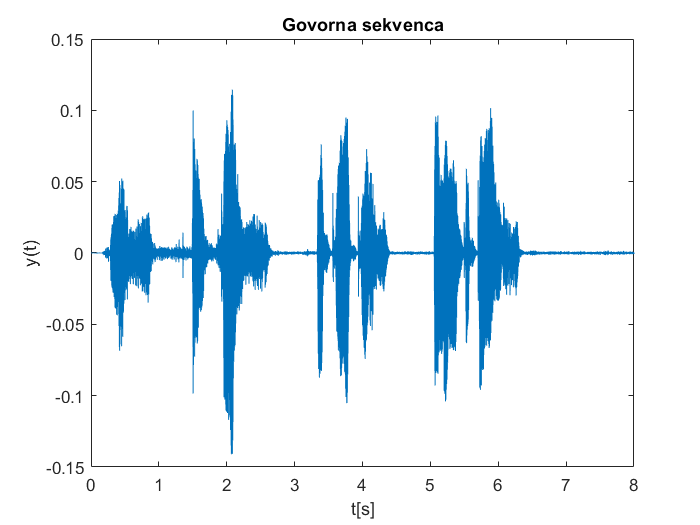


figure
    plot(0:1/fs:(length(y)-1)/fs, y);
    title('Govorna sekvenca'); xlabel('t[s]'); ylabel('y(t)');

y(N+1:2*N) = 0;
y1 = 8*y;
y2 = 0.2*y;
y3 = -5*y;
y4 = -0.2*y;

sound(y1,fs);
pause(6);
sound(y2,fs);
pause(12);

sound(y3,fs);
pause(20);
sound(y4,fs);

y5 = y(end:-1:1);
sound(y5,fs);

factor=3;
ysporo = zeros(1,factor*length(y));

for k = factor:factor:length(ysporo)
    ysporo(k:k+factor-1) = y(k/factor);
end

sound(ysporo)

ybrzo = zeros(1,floor(length(y)/factor))

for k=1:length(ybrzo)
    ybrzo(k) = y(k*factor)
end
sound(ybrzo)

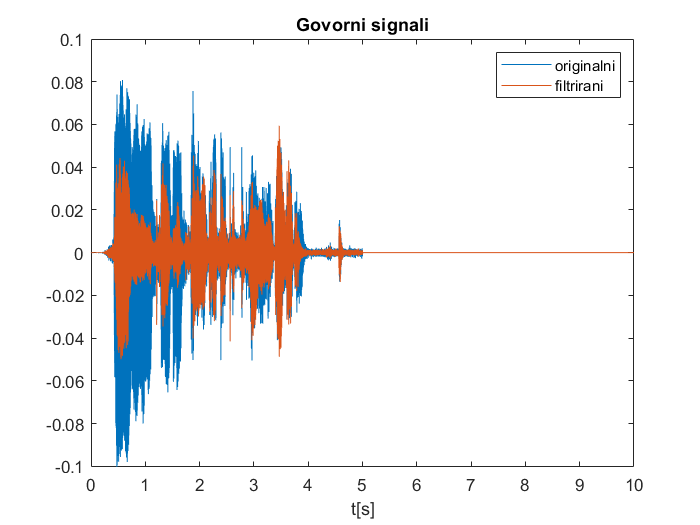

nord = 6;
Wn = [300 3400]/(fs/2);
[b,a] = butter(nord, Wn, 'bandpass');
yf = filter(b,a,y);

figure()
    plot(0:1/fs:(length(y)-1)/fs,y);
    hold on;
    plot(0:1/fs:(length(y)-1)/fs, yf);
    title('Govorni signali'); xlabel('t[s]'); legend('originalni', 'filtrirani');

    
sound(yf,fs);